Textfile = load("FFTOutput2.txt")

Textfile =     0.7300
    1.1200
    0.7600
    0.6900
    0.3500
    0.6300
    0.3900
    0.8200
    0.4700
    0.4800


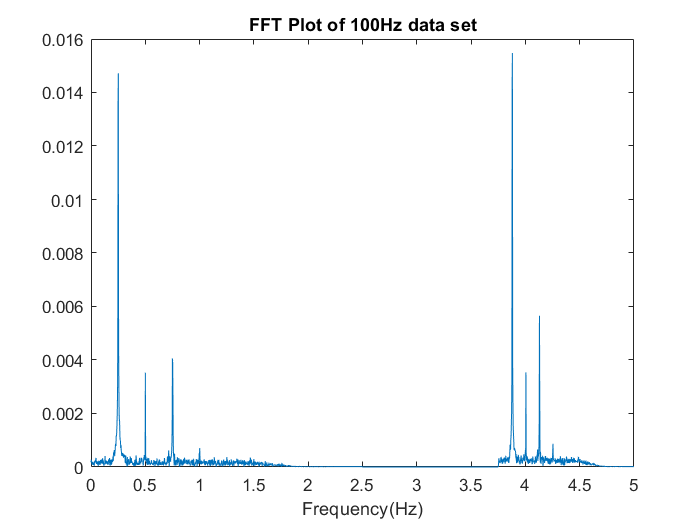

writematrix(Textfile, "FFTOutput2.csv");
FFTData = readtable("FFTOutput2.csv");


N =  4096- 1; 
FFTData = FFTData{:, 1}/N; %data is symmetric, *2 to account for contribution of other half 
fs = 10;
frequency = fs*(0:(N/2))/N;

plot(frequency(1:2048), FFTData(1:2048)); %only plotting the real side of the dataset 
title("FFT Plot of 100Hz data set");
xlabel("Frequency(Hz)");